# **drawLeader**

Draw one or more lines where the first line begin with arrowhead.

## Description

See IGES 5.3,  4.62 Leader (arrow) entity, pp 259-251 ([1])

## Syntax

drawLeader( form, ad1, ad2, xh, yh, xt, yt)

drawLeader( form, ad1, ad2, xh, yh, xt, yt, LineSpec)

## Description

drawLeader( form, ad1, ad2, xh, yh, xt, yt) draw leader with arrow head type *form* and arrowhead point at *xh*,*yh*. 

drawLeader( form, ad1, ad2, xh, yh, xt, yt, LineSpec) set line specification for lines. Color of arrowhead is the same as color of lines.

## Method

The arrowhead is plotted by function **drawArrowhead**.

The leader is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**form **- arrowhead type number: 1,...,12 ([1]). 

   Form Meaning

-      Wedge

-      Triangle

-      Filled Triangle

-      No Arrowhead

-      Circle

-      Filled Circle

-      Rectangle

-      Filled Rectangle

-      Slash

-      Integral Sign 

-      Open Triangle

-      Dimension Origin

**ad1 **- arrowhead height (real scalar >0)

**ad2 **- arrowhead width (real scalar >0)

**xh, yh **-  arrowhead coordinates (real scalar)

**xt, yt  **- tail coordinates  (real vector)

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

## Examples

### Example 1

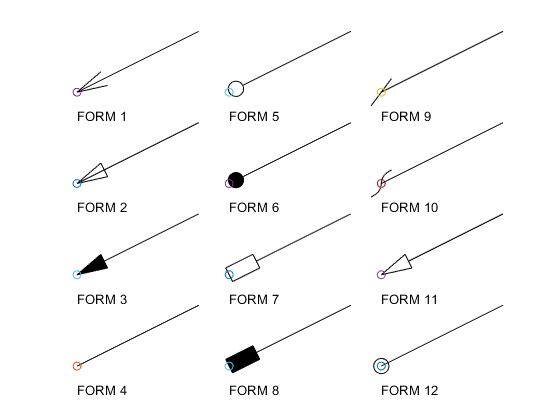

%Arrowhead types (IGES 5.3) 
figure
hold on
axis equal
dx = 2.5;
dy = 1.5;
k = 0;
xh = 0;
yh = 3*dy;
ad2 = 0.5/2;
for n = 1:12
    yh = yh - dy;
    if n == 5 || n == 6 || n == 12
        ad1 = ad2;
    else
        ad1 = 2*ad2;
    end
    % x,y is arrow head point
    drawLeader(n,ad1,ad2,xh,yh,xh+2,yh+1)
    scatter(xh,yh)
    text(xh,yh-dy/4,sprintf('FORM %d',n))
    k = k + 1;
    if k > 3
        k = 0;
        xh = xh + dx;
        yh = 3*dy;
    end
end
axis off

### Example 2

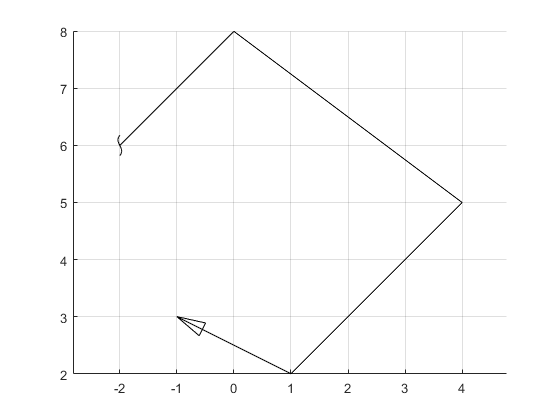

%Arrowhead types (IGES 5.3) 
figure
hold on
axis equal
ad1 = 0.5;
ad2 = ad1/2;
xt = [1 2 3 4 0];
yt = [2 3 4 5 8];
drawLeader( 2,ad1,ad2,-1,3,xt,yt,'k')
drawLeader(10,ad2,ad2,-2,6,xt(end),yt(end),'k')
grid on

## **See Also**

**drawArrow**

## References

  [1] [IGES Initial Graphics Exchange Specification IGES 5.3](http://paulbourke.net/dataformats/iges/IGES.pdf)